## Resultados


Tabla_Cinematica=readtable("Resultados.txt","Delimiter",' ')

Tabla_Cinematica = 1000×13 table
     Tiempo      Aceleracion    Velocidad      Posicion        R_1       theta_1     theta_3        V_1         omega_1       omega_3          a_1         alpha_1     alpha_3 
    _________    ___________    __________    __________    _________    ________    _______    ___________    __________    __________    ___________    _________    ________

            0            0               0             0    -0.099672    -0.46842    2.8737               0             0             0              0            0         


t = xlsread("Resultados Inventor.xlsx");
TablaExcel=array2table(t);
TablaExcel.Properties.VariableNames=["Tiempo","Theta2","w2","A2","Theta3","W3","A3","R1","Vr1","Ar1"]

TablaExcel = 1001×10 table
    Tiempo     Theta2       w2         A2      Theta3      W3         A3         R1         Vr1         Ar1   
    _______    _______    _______    ______    ______    _______    _______    _______    ________    ________

          0          0          0         0    164.65          0          0    0.09967           0           0
    0.00388          0    0.00333    1.7174    164.65    0.00152    0.78572    0.09967           0    -0.00062
    0.00776      3e-05    0.01333    3.4349    164.65     0.0061     1.5714    0.09967           0    -0.00123
    0.01164    0.00012    0.02999    5.1523    164.65    0.01372     2.3571  



tiempo=Tabla_Cinematica.Tiempo;
ExTiempo=TablaExcel.Tiempo;

## Gráficas

### Perfil cinemático del motor

Vmax=double(max(Tabla_Cinematica.Velocidad))*180/pi

Vmax = 370.8232

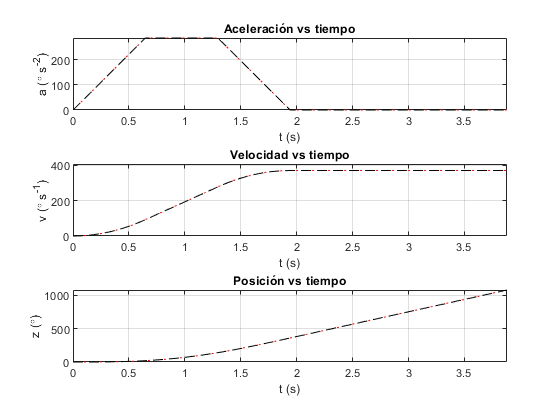

figure()
subplot(3,1,1)
plot(tiempo,Tabla_Cinematica.Aceleracion*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.A2,"k--")
hold off
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (\circ s^{-2})')
xlim([0 ExTiempo(end)])

subplot(3,1,2)
plot(tiempo,Tabla_Cinematica.Velocidad*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.w2,"k--")
hold off
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (\circ s^{-1})')
ylim([0 Vmax*1.1])
xlim([0 ExTiempo(end)])

subplot(3,1,3)
plot(tiempo,Tabla_Cinematica.Posicion*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.Theta2,"k--")
hold off
title('Posición vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (\circ)')
xlim([0 ExTiempo(end)])

### Gráficas de simulación y NR

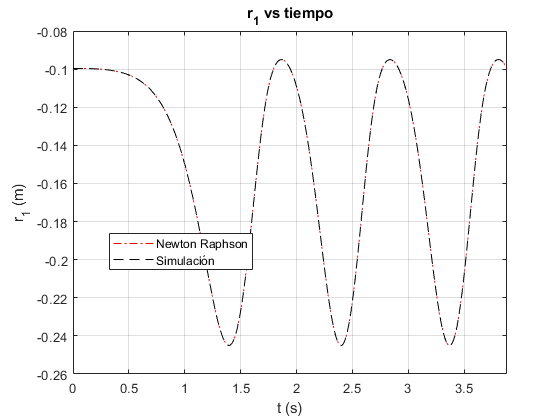

figure()
plot(tiempo,Tabla_Cinematica.R_1,"r-.")
hold on
plot(ExTiempo,-TablaExcel.R1,"k--")
hold off
title("r_1 vs tiempo")
xlabel("t (s)")
ylabel("r_1 (m)")
grid on
xlim([0 tiempo(end)])
legend("Newton Raphson","Simulación","Location","best")

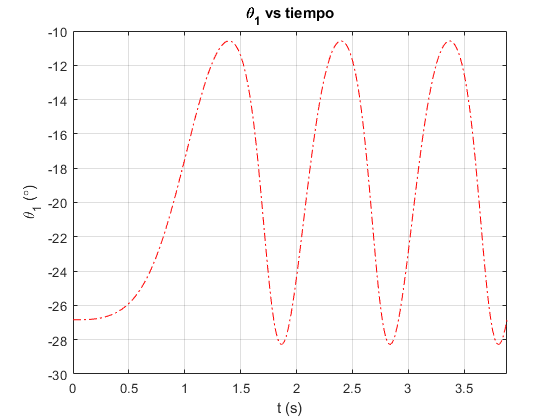


figure()
plot(tiempo,Tabla_Cinematica.theta_1*180/pi,"r-.")
title("\theta_1 vs tiempo")
xlabel("t (s)")
ylabel("\theta_1 (\circ)")
grid on
xlim([0 tiempo(end)])

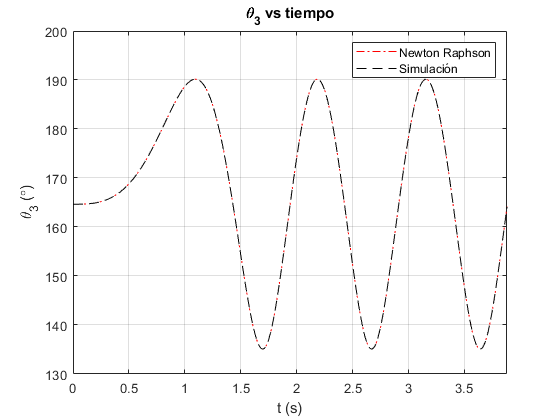


figure()
plot(tiempo,Tabla_Cinematica.theta_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.Theta3,"k--")
hold off
title("\theta_3 vs tiempo")
xlabel("t (s)")
ylabel("\theta_3 (\circ)")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

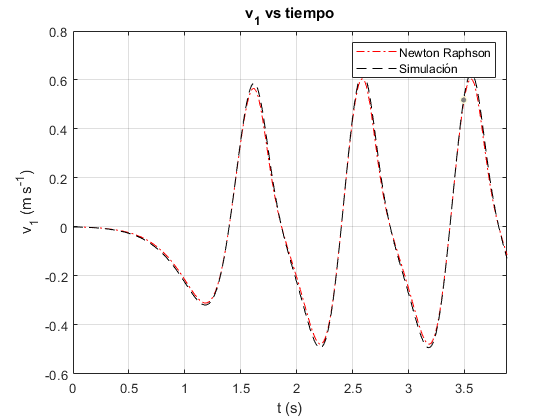

ans =        NaN
         0
    2.3318
    2.0727
    1.7488
    1.4923
    1.5545
    1.5227
    1.4572
    1.3816


ans = NaN



figure()
plot(tiempo,Tabla_Cinematica.V_1,"r-.")
hold on
plot(ExTiempo,TablaExcel.Vr1,"k--")
hold off
title("v_1 vs tiempo")
xlabel("t (s)")
ylabel("v_1 (m s^{-1})")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

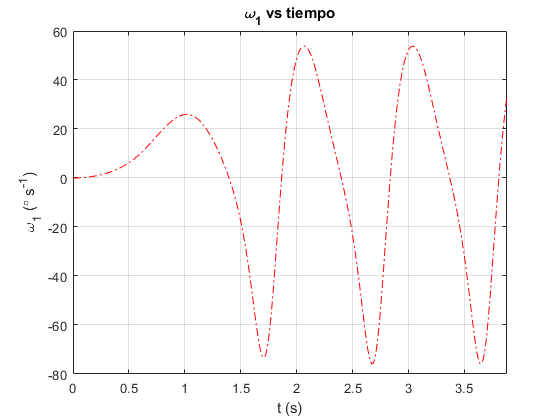

figure()
plot(tiempo,Tabla_Cinematica.omega_1*180/pi,"r-.")
title("\omega_1 vs tiempo")
xlabel("t (s)")
ylabel("\omega_1 (\circ s^{-1})")
grid on
xlim([0 ExTiempo(end)])

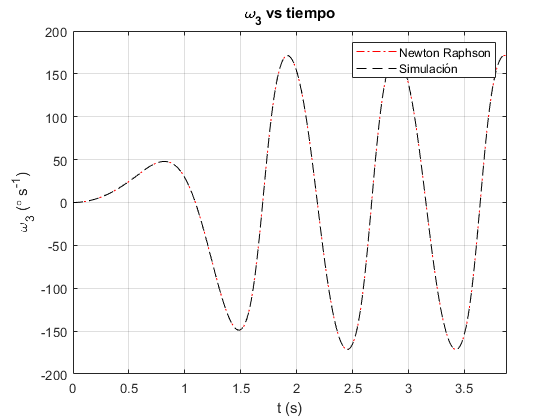


figure()
plot(tiempo,Tabla_Cinematica.omega_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.W3,"k--")
hold off
title("\omega_3 vs tiempo")
xlabel("t (s)")
ylabel("\omega_3 (\circ s^{-1})")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

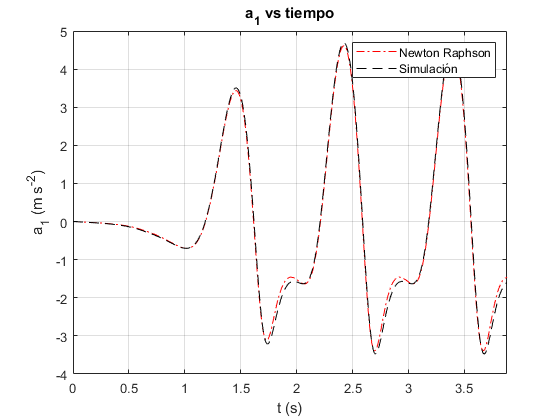


figure()
plot(tiempo,Tabla_Cinematica.a_1,"r-.")
hold on
plot(ExTiempo,TablaExcel.Ar1,"k--")
hold off
title("a_1 vs tiempo")
xlabel("t (s)")
ylabel("a_1 (m s^{-2})")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")

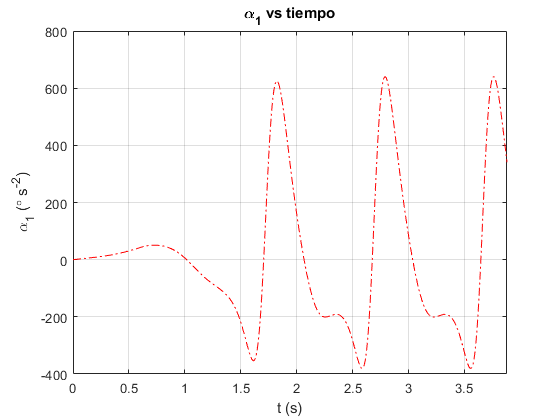


figure()
plot(tiempo,Tabla_Cinematica.alpha_1*180/pi,"r-.")
title("\alpha_1 vs tiempo")
xlabel("t (s)")
ylabel("\alpha_1 (\circ s^{-2})")
grid on
xlim([0 ExTiempo(end)])

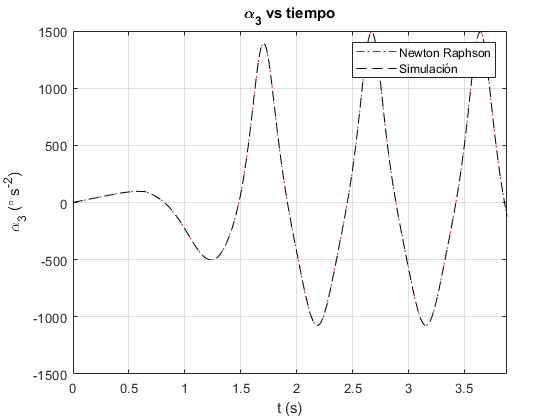


figure()
plot(tiempo,Tabla_Cinematica.alpha_3*180/pi,"r-.")
hold on
plot(ExTiempo,TablaExcel.A3,"k--")
hold off
title("\alpha_3 vs tiempo")
xlabel("t (s)")
ylabel("\alpha_3 (\circ s^{-2})")
grid on
xlim([0 ExTiempo(end)])
legend("Newton Raphson","Simulación")